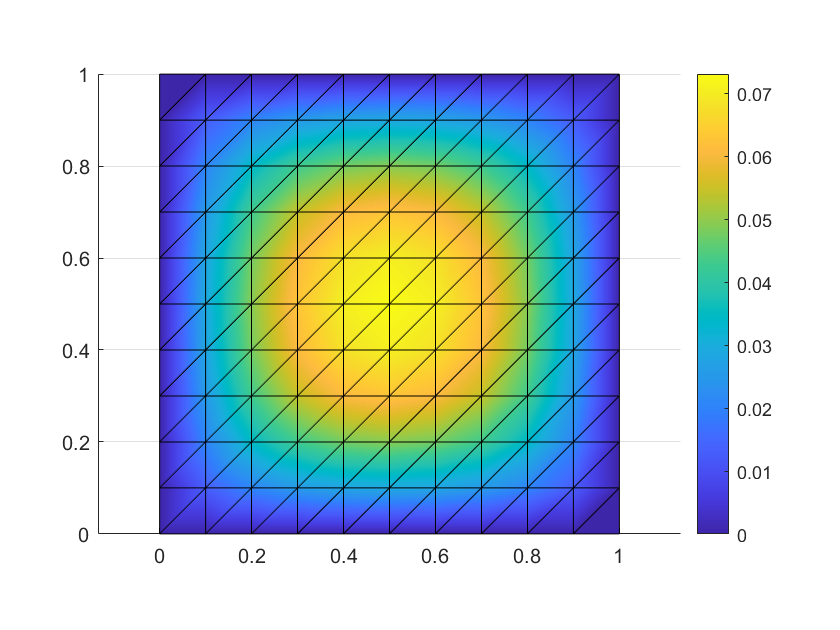

%3.6  femcode.m

% [p,t,b] = squaregrid(m,n) % create grid of N=mn nodes to be listed in p
% generate mesh of T=2(m-1)(n-1) right triangles in unit square
m=11; n=11; % includes boundary nodes, mesh spacing 1/(m-1) and 1/(n-1)
[x,y]=ndgrid((0:m-1)/(m-1),(0:n-1)/(n-1)); % matlab forms x and y lists
p=[x(:),y(:)]; % N by 2 matrix listing x,y coordinates of all N=mn nodes
t=[1,2,m+2; 1,m+2,m+1]; % 3 node numbers for two triangles in first square
t=kron(t,ones(m-1,1))+kron(ones(size(t)),(0:m-2)');
% now t lists 3 node numbers of 2(m-1) triangles in the first mesh row
t=kron(t,ones(n-1,1))+kron(ones(size(t)),(0:n-2)'*m);
% final t lists 3 node numbers of all triangles in T by 3 matrix 
b=[1:m,m+1:m:m*n,2*m:m:m*n,m*n-m+2:m*n-1]; % bottom, left, right, top 
% b = numbers of all 2m+2n **boundary nodes** preparing for U(b)=0

% [K,F] = assemble(p,t) % K and F for any mesh of triangles: linear phi's
N=size(p,1);T=size(t,1); % number of nodes, number of triangles
% p lists x,y coordinates of N nodes, t lists triangles by 3 node numbers
K=sparse(N,N); % zero matrix in sparse format: zeros(N) would be "dense"
F=zeros(N,1); % load vector F to hold integrals of phi's times load f(x,y)

for e=1:T  % integration over one triangular element at a time
  nodes=t(e,:); % row of t = node numbers of the 3 corners of triangle e
  Pe=[ones(3,1),p(nodes,:)]; % 3 by 3 matrix with rows=[1 xcorner ycorner] 
  Area=abs(det(Pe))/2; % area of triangle e = half of parallelogram area
  C=inv(Pe); % columns of C are coeffs in a+bx+cy to give phi=1,0,0 at nodes
  % now compute 3 by 3 Ke and 3 by 1 Fe for element e
  grad=C(2:3,:);Ke=Area*grad'*grad; % element matrix from slopes b,c in grad
  Fe=Area/3; % integral of phi over triangle is volume of pyramid: f(x,y)=1
  % multiply Fe by f at centroid for load f(x,y): one-point quadrature!
  % centroid would be mean(p(nodes,:)) = average of 3 node coordinates
  K(nodes,nodes)=K(nodes,nodes)+Ke; % add Ke to 9 entries of global K
  F(nodes)=F(nodes)+Fe; % add Fe to 3 components of load vector F
end   % all T element matrices and vectors now assembled into K and F

% [Kb,Fb] = dirichlet(K,F,b) % assembled K was singular! K*ones(N,1)=0
% Implement Dirichlet boundary conditions U(b)=0 at nodes in list b
K(b,:)=0; K(:,b)=0; F(b)=0; % put zeros in boundary rows/columns of K and F 
K(b,b)=speye(length(b),length(b)); % put I into boundary submatrix of K
Kb=K; Fb=F; % Stiffness matrix Kb (sparse format) and load vector Fb

% Solving for the vector U will produce U(b)=0 at boundary nodes
U=Kb\Fb;  % The FEM approximation is U_1 phi_1 + ... + U_N phi_N

% Plot the FEM approximation U(x,y) with values U_1 to U_N at the nodes 
trisurf(t,p(:,1),p(:,2),0*p(:,1),U,'edgecolor','k','facecolor','interp');
view(2),axis equal,colorbar